# DAE SYSTEM + Index reduction exercises

## Solution steps

Write DAE symbolically in the form *eq(x,y,...,t) = 0*

         ↓

 [E,G] = massMatrixForm  →  rank(E) = n?  → YES → done (ODE), else:

         ↓ 

Extract invariants (rows where E has zero row)

         ↓

 Differentiate invariants w.r.t. t

         ↓ 

Reassemble DAE with differentiated invariants 

        ↓

 Recompute [E,G], check rank again  (repeat until full rank)

         ↓ 

LU-decompose E → explicit ODE (index-0) form

         ↓ 

(optional) isolate algebraic multiplier from last invariant

clear; clc; close all

## Exercise exam 28-08-2025

DAE system:


$$x'(t)=x(t)y(t)\\
x(t)=t\\
x(t)z(t)=1$$


rewrite in semi-explicit form


$$\mathbf{E}(\mathbf{x},t)\mathbf{x}'=\mathbf{G}(\mathbf{x},t)$$


perform index reduction until $\mathbf{E}^{(k)}(\mathbf{x},t)$ is non singular and DAE is reduced to ODE

#### 1) Write DAE symbolically

syms t x(t) y(t) z(t)
DAE_vars = [x(t), y(t), z(t)].'
DAE0_eqns = [
    diff(x(t), t) - x(t)*y(t);
    x(t) - t;
    x(t)*z(t) - 1
]

#### 2) Mass matrix form (extract E0, G0) and check rank of E0

[E0, G0] = massMatrixForm(DAE0_eqns, DAE_vars)
if(rank(E0)==size(DAE_vars,1))
    disp('System is reduced to ODEs only');
    disp('Index 1');
end

#### 3) Extract invariants

Invariants are rows of G that correspond to zero-rows of E

inv0 = G0(2:3)

Differentiate wrt t and reassemble DAE with diff. invariants

inv0_diff = diff(inv0, t)

#### 4) Reassemble DAE system with differentiated invariants and check rank

Basically start again from 1) until rank is full

DAE1_eqns = E0*diff(DAE_vars) - [G0(1); inv0_diff(1); inv0_diff(2)]

[E1,G1] = massMatrixForm(DAE1_eqns, DAE_vars)
if(rank(E1) == size(DAE_vars,1))
    disp('System is reduced to ODEs only');
    disp('Index 2');
end

#### Extract invariants

Since we don't see zero rows in E directly, apply LU decomposition to E s.t. it becomes triangular

=> read zero rows from the transformed E_reduced and G_reduced, defined as

E_reduced = L⁻¹·E

G_reduced = L⁻¹·G, or p⁻¹·L⁻¹·G if a permutation was used

[L, U, p] = lu(E1)

E2 = L^(-1)*E1
G2 = L^(-1)*G1

inv2 = G2(2)
inv2_diff = diff(inv2, t)

#### Reassemble

DAE2_eqns = E2*diff(DAE_vars) - [G2(1); inv2_diff; G2(3)]

#### Mass matrix and rank

[E3, G3] = massMatrixForm(DAE2_eqns, DAE_vars)

### Results

if(rank(E3)==size(DAE_vars,1))
    disp('System is reduced to ODEs only');
    disp('Index 3');
end
E0
G0
E2
G2
E3
G3
all_invariants = [inv0; inv2]

### N.B if a step asks us to isolate a certain variable (e.g. $\mathbf{\lambda}(t)$) use

% isolate(invariant_eq, variable);

clear; clc; close all;

## EX 23-06-2025

### **First exercise**

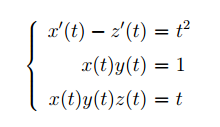

1) Differential index

2) Invariants at each step

3) E and G matrices at each step

#### Write DAE system symbolically

diff_idx =0;
syms t x(t) y(t) z(t)
DAE_vars = [x(t) y(t) z(t)].'
DAE_eqns = [
    diff(x(t),t) - diff(z(t),t) - t^2;
    x(t)*y(t) - 1;
    x(t)*y(t)*z(t) - t
]

**MASS MATRIX FORM**

[E0, G0] = massMatrixForm(DAE_eqns, DAE_vars)

% Rank check
diff_idx = diff_idx+1;
if(rank(E0)==length(DAE_vars))
    disp("System is reduced to ODEs only")
    diff_idx
end

**INVARIANTS EXTRACTION**

inv0 = G0(2:3)
inv0_diff = diff(inv0,t)
DAE_eqns1 = E0 * diff(DAE_vars) - [G0(1); inv0_diff]

**MASS MATRIX FORM 2**

[E1, G1] = massMatrixForm(DAE_eqns1, DAE_vars)

% Rank check --> go directly to LU decomp
% diff_idx = diff_idx+1;
% if(rank(E1)==length(DAE_vars))
%     disp("System is reduced to ODEs only")
%     diff_idx
% end

LU decomp and rewriting of DAE system

[L, U, p] = lu(E1)
E2 = L^-1 * E1
G2 = p^-1 * L^-1 * G1

**RANK CHECK**

% Rank check
diff_idx = diff_idx+1;
if(rank(E2)==length(DAE_vars))
    disp("System is reduced to ODEs only")
    diff_idx
end

Wrap up

disp("Differential index")
diff_idx
disp("List of Invariants")
inv_all = inv0
disp("E(k) matrices")
E_all = [E0; E2]
disp("G(k) vectors")
G_all = [G0; G2]

clear; clc; close all;

### Exercise 2

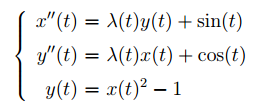

Reduce to order 1 and using dummy vars reduce to index 1

1) diff idx

2) DAE with dummy vars

3) Invariants at each step

4) DAE reduced to idx 1

5) Projection to invariants problem

### Write system symbolically with dummy variables

idx_diff = 0;

% NOTE: WRITE ALL DIFFERENTIAL EQUATIONS FIRST TO AVOID PERMUTATIONS WITH
% LU DECOMP (at first)
syms t x(t) y(t) lambda(t)
% Dummy variables
syms xdot(t) ydot(t)

DAE_vars = [xdot(t) ydot(t) x(t) y(t) lambda(t)].'
DAE_eqns0 = [
    diff(xdot(t),t) - lambda(t)*y(t) - sin(t);
    diff(ydot(t),t) - lambda(t)*x(t) - cos(t);
    diff(x(t),t) == xdot(t);
    diff(y(t),t) == ydot;
    y(t) - x(t)^2 + 1
]

Mass matrix and rank check

[E0, G0] = massMatrixForm(DAE_eqns0, DAE_vars)

% Rank check
if(rank(E0)==length(DAE_vars))
    disp("System is reduced to ODEs only")
    idx_diff
end

Invariant extraction

inv0 = G0(end);
inv0_diff = diff(inv0, t);
idx_diff = idx_diff+1;

Rewriting system

DAE_eqns1 = E0*diff(DAE_vars,t) - [G0(1:end-1); inv0_diff]

Mass matrix and rank check

[E1, G1] = massMatrixForm(DAE_eqns1, DAE_vars)

% Rank check
if(rank(E1)==length(DAE_vars))
    disp("System is reduced to ODEs only")
    idx_diff
end

LU decomp

[L1, U1, p1] = lu(E1)
E2 = L1^-1 * E1
G2 = p1^-1 * L1^-1 * G1

Invariant extraction

inv1 = G2(end)
inv1_diff = diff(inv1)
idx_diff = idx_diff+1;

Rewrite system

DAE_eqns2 = E2*diff(DAE_vars,t) - [G2(1:end-1); inv1_diff]

Mass matrix

[E3, G3] = massMatrixForm(DAE_eqns2, DAE_vars)
% Rank check
if(rank(E3)==length(DAE_vars))
    disp("System is reduced to ODEs only")
    idx_diff
end

LU decomp

[L2, U2, p2] = lu(E3)
E4 = L2^-1 * E3
G4 = p2^-1 * L2^-1 * G3

Invariants

inv2 = G4(end);
inv2_diff = diff(inv2,t);
idx_diff = idx_diff+1;

Rewrite system

DAE_eqns4 = E4*diff(DAE_vars,t) - [G4(1:end-1); inv2_diff]

Mass matrix

[E5, G5] = massMatrixForm(DAE_eqns4, DAE_vars)
% Rank check
if(rank(E5)==length(DAE_vars))
    disp("System is reduced to ODEs only")
    idx_diff
end

### Projection to invariants problem

% Extract lambda from last invariants set??
isolate(inv2==0, lambda(t))

**Wrap up**

disp("Differential index")
idx_diff
disp("List of Invariants")
inv_all = [inv0; inv1; inv2]
disp("E(k) matrices")
E_all = [E0; E1; E3; E5]
disp("G(k) vectors")
G_all = [G0; G1; G3; G5]

clear; clc; close all

## Ex 22-06-2026

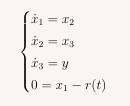

**Writing the system in symbolic form**

idx_diff = 0;
syms t x1(t) x2(t) x3(t) y(t) r(t)
% NOTE: r(t) is NOT a DAE VARIABLE, it's part of the algebric constraint
% but shouldn't be treated as a variable
DAE_vars = [x1(t) x2(t) x3(t) y(t)].'
DAE_eqns0 = [
    diff(x1(t),t) - x2(t);
    diff(x2(t),t) - x3(t);
    diff(x3(t),t) - y(t);
    x1(t) - r(t)
]

Mass matrix form

[E0_0, G0_0] = massMatrixForm(DAE_eqns0, DAE_vars)

**STEP 1:**

Invariants extraction

inv1 = G0_0(end)
inv1_diff = diff(inv1,t)
% Increase differential index
idx_diff = idx_diff + 1

Rewrite the DAE system

DAE_eqns1 = E0_0*diff(DAE_vars,t) - [G0_0(1:end-1); inv1_diff]

Mass matrix form

[E1_0, G1_0] = massMatrixForm(DAE_eqns1, DAE_vars)

**STEP 2**:

LU decomp

[L2, U2, p2] = lu(E1_0)
E1_1 = L2^-1 * E1_0
G1_1 = p2^-1 * L2^-1 * G1_0

Invariant extraction

inv2 = G1_1(end);
inv2_diff = diff(inv2,t);
idx_diff = idx_diff + 1

New system

DAE_eqns2 = E1_1*diff(DAE_vars,t) - [G1_1(1:end-1); inv2_diff]

Mass matrix form

[E2_0, G2_0] = massMatrixForm(DAE_eqns2, DAE_vars)

**STEP 3**:

LU decomp

[L3, U3, p3] = lu(E2_0)
E2_1 = L3^-1 * E2_0
G2_1 = p3^-1 * L3^-1 * G2_0

Invariants extraction

inv3 = G2_1(end);
inv3_diff = diff(inv3,t);
idx_diff = idx_diff + 1

New system

DAE_eqns3 = E2_1*diff(DAE_vars,t) - [G2_1(1:end-1); inv3_diff]

Mass matrix form

[E3_0, G3_0] = massMatrixForm(DAE_eqns3, DAE_vars)

**STEP 4**:

LU decomp

[L4, U4, p4] = lu(E3_0)
E3_1 = L4^-1 * E3_0
G3_1 = p4^-1 * L4^-1 * G3_0

Invariants extraction

inv4 = G3_1(end);
inv4_diff = diff(inv4,t);
idx_diff = idx_diff + 1

New system

DAE_eqns4 = E3_1*diff(DAE_vars,t) - [G3_1(1:end-1); inv4_diff]

Mass matrix form

[E4_0, G4_0] = massMatrixForm(DAE_eqns4, DAE_vars)
% Rank check
if(rank(E4_0)==length(DAE_vars))
    disp("System is reduced to ODEs only")
    idx_diff
end

**Wrap up**

disp("Differential index")
idx_diff
disp("List of Invariants")
inv_all = [inv1; inv2; inv3; inv4]
disp("E(k) matrices")
E_all = [E0_0; E1_1; E2_1; E3_1; E4_0]
disp("G(k) vectors")
G_all = [G0_0; G1_1; G2_1; G3_1; G4_0]

**Ex 2**

idx_diff = 0;
syms t x(t) y(t) lambda(t)
DAE_vars = [x(t)  y(t) lambda(t)].'

$$DAE\_vars = \left(\begin{array}{c} x\left(t\right)\\ y\left(t\right)\\ \lambda \left(t\right) \end{array}\right)$$

DAE_eqns0 = [
    diff(x(t))-y(t)-lambda(t);
    diff(y(t))+x(t);
    x(t)+sin(t)
]

$$DAE\_eqns0 = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)-\lambda \left(t\right)-y\left(t\right)\\ \frac{\partial }{\partial t}y\left(t\right)+x\left(t\right)\\ \sin\left(t\right)+x\left(t\right) \end{array}\right)$$

Mass matrix form

[E0_0, G0_0] = massMatrixForm(DAE_eqns0, DAE_vars)

$$E0\_0 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$G0\_0 = \left(\begin{array}{c} \lambda \left(t\right)+y\left(t\right)\\ -x\left(t\right)\\ -\sin\left(t\right)-x\left(t\right) \end{array}\right)$$

**STEP 1:**

invariants

inv1 = G0_0(end);
inv1_diff = diff(inv1);
idx_diff = idx_diff + 1

idx_diff = 1

new system

DAE_eqns1 = E0_0*diff(DAE_vars)-[G0_0(1:end-1); inv1_diff]

$$DAE\_eqns1 = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)-\lambda \left(t\right)-y\left(t\right)\\ \frac{\partial }{\partial t}y\left(t\right)+x\left(t\right)\\ \frac{\partial }{\partial t}x\left(t\right)+\cos\left(t\right) \end{array}\right)$$

MMF

[E1_0, G1_0] = massMatrixForm(DAE_eqns1, DAE_vars)

$$E1\_0 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 1 & 0 & 0 \end{array}\right)$$

$$G1\_0 = \left(\begin{array}{c} \lambda \left(t\right)+y\left(t\right)\\ -x\left(t\right)\\ -\cos\left(t\right) \end{array}\right)$$

LU decomp

[L1, U1, p1] = lu(E1_0)

$$L1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 1 & 0 & 1 \end{array}\right)$$

$$U1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 0 \end{array}\right)$$

p1 =      1     0     0
     0     1     0
     0     0     1


E1_1 = L1^-1 * E1_0

$$E1\_1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 0 \end{array}\right)$$

G1_1 = p1^-1 * L1^-1 * G1_0

$$G1\_1 = \left(\begin{array}{c} \lambda \left(t\right)+y\left(t\right)\\ -x\left(t\right)\\ -\cos\left(t\right)-\lambda \left(t\right)-y\left(t\right) \end{array}\right)$$

**STEP 2:**

invariants

inv2 = G1_1(end);
inv2_diff = diff(inv2);
idx_diff = idx_diff + 1

idx_diff = 2

new system

DAE_eqns2 = E1_1*diff(DAE_vars)-[G1_1(1:end-1); inv2_diff]

$$DAE\_eqns2 = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)-\lambda \left(t\right)-y\left(t\right)\\ \frac{\partial }{\partial t}y\left(t\right)+x\left(t\right)\\ \frac{\partial }{\partial t}\lambda \left(t\right)-\sin\left(t\right)+\frac{\partial }{\partial t}y\left(t\right) \end{array}\right)$$

MMF

[E2_0, G2_0] = massMatrixForm(DAE_eqns2, DAE_vars)

$$E2\_0 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 1 & 1 \end{array}\right)$$

$$G2\_0 = \left(\begin{array}{c} \lambda \left(t\right)+y\left(t\right)\\ -x\left(t\right)\\ \sin\left(t\right) \end{array}\right)$$

LU decomp

[L2, U2, p2] = lu(E2_0)

$$L2 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 1 & 1 \end{array}\right)$$

$$U2 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

p2 =      1     0     0
     0     1     0
     0     0     1


E2_1 = L2^-1 * E2_0

$$E2\_1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

G2_1 = p2^-1 * L2^-1 * G2_0

$$G2\_1 = \left(\begin{array}{c} \lambda \left(t\right)+y\left(t\right)\\ -x\left(t\right)\\ \sin\left(t\right)+x\left(t\right) \end{array}\right)$$

**Wrap up**

disp("Differential index")

Differential index


idx_diff

idx_diff = 2

disp("List of Invariants")

List of Invariants


inv_all = [inv1; inv2]

$$inv\_all = \left(\begin{array}{c} -\sin\left(t\right)-x\left(t\right)\\ -\cos\left(t\right)-\lambda \left(t\right)-y\left(t\right) \end{array}\right)$$

disp("E(k) matrices")

E(k) matrices


E_all = [E0_0; E1_1; E2_1]

$$E\_all = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 0\\ 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 0\\ 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

disp("G(k) vectors")

G(k) vectors


G_all = [G0_0; G1_1; G2_1]

$$G\_all = \left(\begin{array}{c} \lambda \left(t\right)+y\left(t\right)\\ -x\left(t\right)\\ -\sin\left(t\right)-x\left(t\right)\\ \lambda \left(t\right)+y\left(t\right)\\ -x\left(t\right)\\ -\cos\left(t\right)-\lambda \left(t\right)-y\left(t\right)\\ \lambda \left(t\right)+y\left(t\right)\\ -x\left(t\right)\\ \sin\left(t\right)+x\left(t\right) \end{array}\right)$$